First, the bike routes of the data is plotted, the begin point is displayd with a circle.

dataPath = fullfile("Data/location_data (1)");
dataDirectory = dir(dataPath);
bikeData = [];

for i = 3:length(dataDirectory)
    baseFileName = dataDirectory(i).name;
    fullFileName = fullfile(dataPath, baseFileName);
    table = readtable(fullFileName);
    bikeData{end+1} = table(:, [2, 5:15, 17]);
end


for i = 1:length(bikeData)
    currentData = bikeData{i};

    beginx = currentData.longitude(1);
    beginy = currentData.latitude(1);
end

Now, the GPS coordinates are converted to (x, y) coordinates.

alt = 30;  % 30 meters is an approximate altitude in Enschede
origin = [bikeData{1}.latitude(1), bikeData{1}.longitude(1), alt];

hold on
for i = 1:length(bikeData)
    currentData = bikeData{i};
    [x,y] = latlon2local(currentData.latitude, currentData.longitude, alt, origin);
    plot(x, y)
    bikeData{i}.("x") = x;
    bikeData{i}.("y") = y;
end
hold off

Determine which messages the nodes should receive

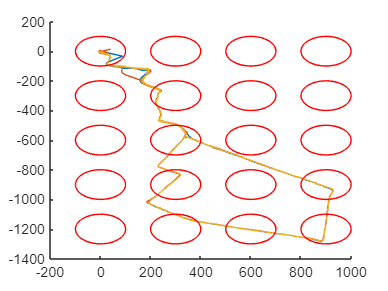

networkSimulator = wirelessNetworkSimulator.init;

amountX = 3;
amountY = 4;

function nodes = createGrid(amountX, amountY)
    distance = 300;
    nodes = [];
    nodeID = 1;
    
    for y = 0:distance:amountY*distance
        for x = 0:distance:amountX*distance
            config = bluetoothMeshProfileConfig(ElementAddress=dec2hex(nodeID,4),...
                NetworkTransmissions=1);
            node = bluetoothLENode("broadcaster-observer", Name="Grid" + nodeID);
            node.Position = [x -y 0];
            nodes{end+1} = node;
            nodeID = nodeID + 1;
        end
    end
end

grid = createGrid(amountX, amountY);

function h = circle(x,y,r)
    hold on
    th = 0:pi/50:2*pi;
    xunit = r * cos(th) + x;
    yunit = r * sin(th) + y;
    h = plot(xunit, yunit, Color="red", MarkerSize=0.1);
    hold off
end

hold on
for i=1:length(grid)
    circle(grid{i}.Position(1), grid{i}.Position(2), 100);
end
hold off


function x = inRange(position1, position2)
    distance = sqrt((position1(1) - position2(1))^2 + (position1(2) - position2(2))^2);
    x = distance <= 100;
end

function toReceive = determineToReceive(grid, amountX, amountY, bikeData)
    filePath = "Output\messagesToReceive\grid" + amountX + "x" + amountY + ".mat"
    if false
    % if isfile(filePath)
        load(filePath, "toReceive")
    else

        toReceive = cell([1 length(grid)])
        
        for k = 1:length(grid)
            k
            % receive = cell([1 (length(bikeData)*height(bikeData{1}))]);
            toReceive{k} = [];
            % for i = 1:length(bikeData)
                i=1;
                % for j = 1:height(bikeData{i})
                for j = 450:500
                    messagePosition = [bikeData{i}.x(j) bikeData{i}.y(j)];
                    if inRange(grid{k}.Position, messagePosition)
                        toReceive{k}{end + 1} = bikeData{i}.x_id(j);                        
                    end
                end
            % end
            % toReceive{k} = receive;
        end
        save(filePath, "toReceive")
    end
end

toReceive = determineToReceive(grid, amountX, amountY, bikeData);

filePath = "Output\messagesToReceive\grid3x4.mat"

toReceive = 1×20 cell array
    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}


k = 1

k = 2

k = 3

k = 4

k = 5

k = 6

k = 7

k = 8

k = 9

k = 10

k = 11

k = 12

k = 13

k = 14

k = 15

k = 16

k = 17

k = 18

k = 19

k = 20

Setup simulation

numNodes = 3;

config = bluetoothMeshProfileConfig(ElementAddress=dec2hex(length(grid)+1, 4),...
        NetworkTransmissions=1);

config.Relay = false;


bike1 = bluetoothLENode("broadcaster-observer", Name="Bike1", MeshConfig=config);
bike2 = bluetoothLENode("broadcaster-observer", Name="Bike2");

bikes = {bike1 bike2}

bikes = 1×2 cell array
    {1×1 bluetoothLENode}    {1×1 bluetoothLENode}




traffic = networkTrafficOnOff(OnTime=0.02, OffTime=0.08, PacketSize=8, GeneratePacket=true, DataRate=1000);
addTrafficSource(bike1, traffic, ...
    SourceAddress=bike1.MeshConfig.ElementAddress, ...
    DestinationAddress=grid{5}.MeshConfig.ElementAddress);

simulationData = struct;
simulationData.bikeData = bikeData;
simulationData.simulator = networkSimulator;
simulationData.bikes = bikes;
simulationData.traffic = traffic;
global iteration
iteration = 450;

Create listener to process received data

global receivedData;
receivedData = []


receivedData =

     []





function processData(Node, EventData)
    global receivedData;
    fprintf("Message received")
    message = EventData.Data.Message;

    received_id = typecast(uint8(transpose(message)), 'uint32')
    receivedData(end+1) = received_id(1);
end

% addlistener(grid{1}, "MeshAppDataReceived", @processData);
addlistener(bike1, "MeshAppDataReceived", @processData);


Create listener for sending data

function transmitData(node, EventData)
    global traffic
    traffic.GeneratePacket = false;
end

% addlistener(bike1, "PacketTransmissionStarted", @transmitData);


Create function which sets position of the bike 

function sendData(~, userData)
    global iteration;

    for i = 1:(length(userData.bikes(1)))
        userData.bikes{i}.Position = [userData.bikeData{i}.x(iteration) ...
            userData.bikeData{i}.y(iteration) 0];
    end

    id = uint32(userData.bikeData{1}.x_id(iteration))

    bytes = typecast(id, "uint8")

    userData.traffic.ApplicationData = bytes;
    iteration = iteration + 1;
end


addNodes(networkSimulator, bike1);
addNodes(networkSimulator, grid);
scheduleAction(networkSimulator, @sendData, simulationData, 0, 0.1);

Bluetooth messages will now be simulated

simulationTime = 5;

run(networkSimulator,simulationTime);

Message received

received_id = 1×2 uint32 row vector
   16843009   16843009


id = uint32
11494

bytes = 1×4 uint8 row vector
   230    44     0     0


Message received

received_id = 1×2 uint32 row vector
   11494       0


Message received

received_id = 1×2 uint32 row vector
   11494       0


Message received

received_id = 1×2 uint32 row vector
   11494       0


Message received

received_id = 1×2 uint32 row vector
   11494       0


Message received

received_id = 1×2 uint32 row vector
   11494       0


Message received

received_id = 1×2 uint32 row vector
   11494       0


Message received

received_id = 1×2 uint32 row vector
   11494       0


Message received

received_id = 1×2 uint32 row vector
   11494       0


Message received

received_id = 1×2 uint32 row vector
   11494       0


Message received

received_id = 1×2 uint32 row vector
   11494       0


Message received

received_id = 1×2 uint32 row vector
   11494       0


Message received

received_id = 1×2 uint32 row vector
   11494       0


Message received

received_id = 1×2 uint32 row vector
   11494       0


Message received

received_id = 1×2 uint32 row vector
   11494       0


Message received

received_id = 1×2 uint32 row vector
   11494       0


Message received

received_id = 1×2 uint32 row vector
   11494       0


Message received

received_id = 1×2 uint32 row vector
   11494       0


Message received

received_id = 1×2 uint32 row vector
   11494       0


Message received

received_id = 1×2 uint32 row vector
   11494       0


Message received

received_id = 1×2 uint32 row vector
   11494       0


Message received

received_id = 1×2 uint32 row vector
   11494       0


Message received

received_id = 1×2 uint32 row vector
   11494       0


Message received

received_id = 1×2 uint32 row vector
   11494       0


Message received

received_id = 1×2 uint32 row vector
   11494       0


Message received

received_id = 1×2 uint32 row vector
   11494       0


Message received

received_id = 1×2 uint32 row vector
   11494       0


Message received

received_id = 1×2 uint32 row vector
   11494       0


Message received

received_id = 1×2 uint32 row vector
   11494       0


Message received

received_id = 1×2 uint32 row vector
   11494       0


Message received

received_id = 1×2 uint32 row vector
   11494       0


Message received

received_id = 1×2 uint32 row vector
   11494       0


Message received

received_id = 1×2 uint32 row vector
   11494       0


Message received

received_id = 1×2 uint32 row vector
   11494       0


Message received

received_id = 1×2 uint32 row vector
   11494       0


Message received

received_id = 1×2 uint32 row vector
   11494       0


Message received

received_id = 1×2 uint32 row vector
   11494       0


Message received

received_id = 1×2 uint32 row vector
   11494       0


Message received

received_id = 1×2 uint32 row vector
   11494       0


Message received

received_id = 1×2 uint32 row vector
   11494       0


Message received

received_id = 1×2 uint32 row vector
   11494       0


Message received

received_id = 1×2 uint32 row vector
   11494       0


Message received

received_id = 1×2 uint32 row vector
   11494       0


Message received

received_id = 1×2 uint32 row vector
   11494       0


Message received

received_id = 1×2 uint32 row vector
   11494       0


Message received

received_id = 1×2 uint32 row vector
   11494       0


Message received

received_id = 1×2 uint32 row vector
   11494       0


Message received

received_id = 1×2
   11494       0


Message received

received_id = 1×2
   11494       0


Message received

received_id = 1×2
   11494       0


Message received

received_id = 1×2
   11494       0


Message received

received_id = 1×2
   11494       0


Message received

received_id = 1×2
   11494       0


Message received

received_id = 1×2
   11494       0


Message received

received_id = 1×2
   11494       0


Message received

received_id = 1×2
   11494       0


Message received

received_id = 1×2
   11494       0


Message received

received_id = 1×2
   11494       0


Message received

received_id = 1×2
   11494       0


Message received

received_id = 1×2
   11494       0


Message received

received_id = 1×2
   11494       0


Message received

received_id = 1×2
   11494       0


Message received

received_id = 1×2
   11494       0


Message received

received_id = 1×2
   11494       0


Message received

received_id = 1×2
   11494       0


Message received

received_id = 1×2
   11494       0


Message received

received_id = 1×2
   11494       0


Message received

received_id = 1×2
   11494       0


Message received

received_id = 1×2
   11494       0


Message received

received_id = 1×2
   11494       0


Message received

received_id = 1×2
   11494       0


Message received

received_id = 1×2
   11494       0


Message received

received_id = 1×2
   11494       0


Message received

received_id = 1×2
   11494       0


Message received

received_id = 1×2
   11494       0


Message received

received_id = 1×2
   11494       0


Message received

received_id = 1×2
   11494       0


Message received

received_id = 1×2
   11494       0


Message received

received_id = 1×2
   11494       0


Message received

received_id = 1×2
   11494       0


Message received

received_id = 1×2
   11494       0


Message received

received_id = 1×2
   11494       0


Message received

received_id = 1×2
   11494       0


Message received

received_id = 1×2
   11494       0


Message received

received_id = 1×2
   11494       0


Message received

received_id = 1×2
   11494       0


Message received

received_id = 1×2
   11494       0


Message received

received_id = 1×2
   11494       0


Message received

received_id = 1×2
   11494       0


Message received

received_id = 1×2
   11494       0


Message received

received_id = 1×2
   11494       0


Message received

received_id = 1×2
   11494       0


Message received

received_id = 1×2
   11494       0


Message received

received_id = 1×2
   11494       0


Message received

received_id = 1×2
   11494       0


Message received

received_id = 1×2
   11494       0


Message received

received_id = 1×2
   11494       0


Message received

received_id = 1×2
   11494       0


Message received

received_id = 1×2
   11494       0


Message received

received_id = 1×2
   11494       0


Message received

received_id = 1×2
   11494       0


Message received

received_id = 1×2
   11494       0


Message received

received_id = 1×2
   11494       0


Message received

received_id = 1×2
   11494       0


Message received

received_id = 1×2
   11494       0


Message received

received_id = 1×2
   11494       0


Message received

received_id = 1×2
   11494       0


Message received

received_id = 1×2
   11494       0


Message received

received_id = 1×2
   11494       0


Message received

received_id = 1×2
   11494       0


Message received

received_id = 1×2
   11494       0


Message received

received_id = 1×2
   11494       0


Message received

received_id = 1×2
   11494       0


Message received

received_id = 1×2
   11494       0


Message received

received_id = 1×2
   11494       0


Message received

received_id = 1×2
   11494       0


Message received

received_id = 1×2
   11494       0


Message received

received_id = 1×2
   11494       0


Message received

received_id = 1×2
   11494       0


Message received

received_id = 1×2
   11494       0


Message received

received_id = 1×2
   11494       0


Message received

received_id = 1×2
   11494       0


Message received

received_id = 1×2
   11494       0


Message received

received_id = 1×2
   11494       0


Message received

received_id = 1×2
   11494       0


Message received

received_id = 1×2
   11494       0


Message received

received_id = 1×2
   11494       0


Message received

received_id = 1×2
   11494       0


Message received

received_id = 1×2
   11494       0


Message received

received_id = 1×2
   11494       0


Message received

received_id = 1×2
   11494       0


Message received

received_id = 1×2
   11494       0


Message received

received_id = 1×2
   11494       0


Message received

received_id = 1×2
   11494       0


Message received

received_id = 1×2
   11494       0


Message received

received_id = 1×2
   11494       0


Message received

received_id = 1×2
   11494       0


Message received

received_id = 1×2
   11494       0


Message received

received_id = 1×2
   11494       0


Message received

received_id = 1×2
   11494       0


Message received

received_id = 1×2
   11494       0


Message received

received_id = 1×2
   11494       0


Message received

received_id = 1×2
   11494       0


Message received

received_id = 1×2
   11494       0


Message received

received_id = 1×2
   11494       0


Message received

received_id = 1×2
   11494       0


Message received

received_id = 1×2
   11494       0


Message received

received_id = 1×2
   11494       0


Message received

received_id = 1×2
   11494       0


Message received

received_id = 1×2
   11494       0


Message received

received_id = 1×2
   11494       0


Message received

received_id = 1×2
   11494       0


Message received

received_id = 1×2
   11494       0


Message received

received_id = 1×2
   11494       0


Message received

received_id = 1×2
   11494       0


Message received

received_id = 1×2
   11494       0


Message received

received_id = 1×2
   11494       0


Message received

received_id = 1×2
   11494       0


Message received

received_id = 1×2
   11494       0


Message received

received_id = 1×2
   11494       0


Message received

received_id = 1×2
   11494       0


Message received

received_id = 1×2
   11494       0


Message received

received_id = 1×2
   11494       0


Message received

received_id = 1×2
   11494       0


Message received

received_id = 1×2
   11494       0


Message received

received_id = 1×2
   11494       0


Message received

received_id = 1×2
   11494       0


Message received

received_id = 1×2
   11494       0


Message received

received_id = 1×2
   11494       0


Message received

received_id = 1×2
   11494       0


Message received

received_id = 1×2
   11494       0


Message received

received_id = 1×2
   11494       0


Message received

received_id = 1×2
   11494       0


Message received

received_id = 1×2
   11494       0


Message received

received_id = 1×2
   11494       0


Message received

received_id = 1×2
   11494       0


Message received

received_id = 1×2
   11494       0


Message received

received_id = 1×2
   11494       0


Message received

received_id = 1×2
   11494       0


Message received

received_id = 1×2
   11494       0


Message received

received_id = 1×2
   11494       0


Message received

received_id = 1×2
   11494       0


Message received

received_id = 1×2
   11494       0


Message received

received_id = 1×2
   11494       0


Message received

received_id = 1×2
   11494       0


Message received

received_id = 1×2
   11494       0


Message received

received_id = 1×2
   11494       0


Message received

received_id = 1×2
   11494       0


Message received

received_id = 1×2
   11494       0


Message received

received_id = 1×2
   11494       0


Message received

received_id = 1×2
   11494       0


Message received

received_id = 1×2
   11494       0


Message received

received_id = 1×2
   11494       0


Message received

received_id = 1×2
   11494       0


Message received

received_id = 1×2
   11494       0


Message received

received_id = 1×2
   11494       0


Message received

received_id = 1×2
   11494       0


Message received

received_id = 1×2
   11494       0


Message received

received_id = 1×2
   11494       0


Message received

received_id = 1×2
   11494       0


Message received

received_id = 1×2
   11494       0


Message received

received_id = 1×2
   11494       0


Message received

received_id = 1×2
   11494       0


Message received

received_id = 1×2
   11494       0


Message received

received_id = 1×2
   11494       0


Message received

received_id = 1×2
   11494       0


Message received

received_id = 1×2
   11494       0


Message received

received_id = 1×2
   11494       0


Message received

received_id = 1×2
   11494       0


Message received

received_id = 1×2
   11494       0


Message received

received_id = 1×2
   11494       0


Message received

received_id = 1×2
   11494       0


Message received

received_id = 1×2
   11494       0


Message received

received_id = 1×2
   11494       0


Message received

received_id = 1×2
   11494       0


Message received

received_id = 1×2
   11494       0


Message received

received_id = 1×2
   11494       0


Message received

received_id = 1×2
   11494       0


Message received

received_id = 1×2
   11494       0


Message received

received_id = 1×2
   11494       0


Message received

received_id = 1×2
   11494       0


Message received

received_id = 1×2
   11494       0


Message received

received_id = 1×2
   11494       0


Message received

received_id = 1×2
   11494       0


Message received

received_id = 1×2
   11494       0


Message received

received_id = 1×2
   11494       0


Message received

received_id = 1×2
   11494       0


Message received

received_id = 1×2
   11494       0


Message received

received_id = 1×2
   11494       0


Message received

received_id = 1×2
   11494       0


Message received

received_id = 1×2
   11494       0


Message received

received_id = 1×2
   11494       0


Message received

received_id = 1×2
   11494       0


Message received

received_id = 1×2
   11494       0


Message received

received_id = 1×2
   11494       0


Message received

received_id = 1×2
   11494       0


Message received

received_id = 1×2
   11494       0


Message received

received_id = 1×2
   11494       0


Message received

received_id = 1×2
   11494       0


Message received

received_id = 1×2
   11494       0


Message received

received_id = 1×2
   11494       0


Message received

received_id = 1×2
   11494       0


Message received

received_id = 1×2
   11494       0


Message received

received_id = 1×2
   11494       0


Message received

received_id = 1×2
   11494       0


Message received

received_id = 1×2
   11494       0


Message received

received_id = 1×2
   11494       0


Message received

received_id = 1×2
   11494       0


Message received

received_id = 1×2
   11494       0


Message received

received_id = 1×2
   11494       0


Message received

received_id = 1×2
   11494       0


Message received

received_id = 1×2
   11494       0


Message received

received_id = 1×2
   11494       0


Message received

received_id = 1×2
   11494       0


Message received

received_id = 1×2
   11494       0


Message received

received_id = 1×2
   11494       0


Message received

received_id = 1×2
   11494       0


Message received

received_id = 1×2
   11494       0


Message received

received_id = 1×2
   11494       0


Message received

received_id = 1×2
   11494       0


Message received

received_id = 1×2
   11494       0


Message received

received_id = 1×2
   11494       0


Message received

received_id = 1×2
   11494       0


Message received

received_id = 1×2
   11494       0


Message received

received_id = 1×2
   11494       0


Message received

received_id = 1×2
   11494       0


Message received

received_id = 1×2
   11494       0


Message received

received_id = 1×2
   11494       0


Message received

received_id = 1×2
   11494       0


Message received

received_id = 1×2
   11494       0


Message received

received_id = 1×2
   11494       0


Message received

received_id = 1×2
   11494       0


Message received

received_id = 1×2
   11494       0


Message received

received_id = 1×2
   11494       0


Message received

received_id = 1×2
   11494       0


Message received

received_id = 1×2
   11494       0


Message received

received_id = 1×2
   11494       0


Message received

received_id = 1×2
   11494       0


Message received

received_id = 1×2
   11494       0


Message received

received_id = 1×2
   11494       0


Message received

received_id = 1×2
   11494       0


Message received

received_id = 1×2
   11494       0


Message received

received_id = 1×2
   11494       0


Message received

received_id = 1×2
   11494       0


Message received

received_id = 1×2
   11494       0


Message received

received_id = 1×2
   11494       0


Message received

received_id = 1×2
   11494       0


Message received

received_id = 1×2
   11494       0


Message received

received_id = 1×2
   11494       0


Message received

received_id = 1×2
   11494       0


Message received

received_id = 1×2
   11494       0


Message received

received_id = 1×2
   11494       0


Message received

received_id = 1×2
   11494       0


Message received

received_id = 1×2
   11494       0


Message received

received_id = 1×2
   11494       0


Message received

received_id = 1×2
   11494       0


Message received

received_id = 1×2
   11494       0


Message received

received_id = 1×2
   11494       0


Message received

received_id = 1×2
   11494       0


Message received

received_id = 1×2
   11494       0


Message received

received_id = 1×2
   11494       0


Message received

received_id = 1×2
   11494       0


Message received

received_id = 1×2
   11494       0


Message received

received_id = 1×2
   11494       0


Message received

received_id = 1×2
   11494       0


Message received

received_id = 1×2
   11494       0


Message received

received_id = 1×2
   11494       0


Message received

received_id = 1×2
   11494       0


Message received

received_id = 1×2
   11494       0


Message received

received_id = 1×2
   11494       0


Message received

received_id = 1×2
   11494       0


Message received

received_id = 1×2
   11494       0


Message received

received_id = 1×2
   11494       0


id = uint32
11495

bytes = 1×4
   231    44     0     0


Message received

received_id = 1×2
   11495       0


Message received

received_id = 1×2
   11495       0


Message received

received_id = 1×2
   11495       0


Message received

received_id = 1×2
   11495       0


Message received

received_id = 1×2
   11495       0


Message received

received_id = 1×2
   11495       0


Message received

received_id = 1×2
   11495       0


Message received

received_id = 1×2
   11495       0


Message received

received_id = 1×2
   11495       0


Message received

received_id = 1×2
   11495       0


Message received

received_id = 1×2
   11495       0


Message received

received_id = 1×2
   11495       0


Message received

received_id = 1×2
   11495       0


Message received

received_id = 1×2
   11495       0


Message received

received_id = 1×2
   11495       0


Message received

received_id = 1×2
   11495       0


Message received

received_id = 1×2
   11495       0


Message received

received_id = 1×2
   11495       0


Message received

received_id = 1×2
   11495       0


Message received

received_id = 1×2
   11495       0


Message received

received_id = 1×2
   11495       0


Message received

received_id = 1×2
   11495       0


Message received

received_id = 1×2
   11495       0


Message received

received_id = 1×2
   11495       0


Message received

received_id = 1×2
   11495       0


Message received

received_id = 1×2
   11495       0


Message received

received_id = 1×2
   11495       0


Message received

received_id = 1×2
   11495       0


Message received

received_id = 1×2
   11495       0


Message received

received_id = 1×2
   11495       0


Message received

received_id = 1×2
   11495       0


Message received

received_id = 1×2
   11495       0


Message received

received_id = 1×2
   11495       0


Message received

received_id = 1×2
   11495       0


Message received

received_id = 1×2
   11495       0


Message received

received_id = 1×2
   11495       0


Message received

received_id = 1×2
   11495       0


Message received

received_id = 1×2
   11495       0


Message received

received_id = 1×2
   11495       0


Message received

received_id = 1×2
   11495       0


Message received

received_id = 1×2
   11495       0


Message received

received_id = 1×2
   11495       0


Message received

received_id = 1×2
   11495       0


Message received

received_id = 1×2
   11495       0


Message received

received_id = 1×2
   11495       0


Message received

received_id = 1×2
   11495       0


Message received

received_id = 1×2
   11495       0


Message received

received_id = 1×2
   11495       0


Message received

received_id = 1×2
   11495       0


Message received

received_id = 1×2
   11495       0


Message received

received_id = 1×2
   11495       0


Message received

received_id = 1×2
   11495       0


Message received

received_id = 1×2
   11495       0


Message received

received_id = 1×2
   11495       0


Message received

received_id = 1×2
   11495       0


Message received

received_id = 1×2
   11495       0


Message received

received_id = 1×2
   11495       0


Message received

received_id = 1×2
   11495       0


Message received

received_id = 1×2
   11495       0


Message received

received_id = 1×2
   11495       0


Message received

received_id = 1×2
   11495       0


Message received

received_id = 1×2
   11495       0


Message received

received_id = 1×2
   11495       0


Message received

received_id = 1×2
   11495       0


Message received

received_id = 1×2
   11495       0


Message received

received_id = 1×2
   11495       0


Message received

received_id = 1×2
   11495       0


Message received

received_id = 1×2
   11495       0


Message received

received_id = 1×2
   11495       0


Message received

received_id = 1×2
   11495       0


Message received

received_id = 1×2
   11495       0


Message received

received_id = 1×2
   11495       0


Message received

received_id = 1×2
   11495       0


Message received

received_id = 1×2
   11495       0


Message received

received_id = 1×2
   11495       0


Message received

received_id = 1×2
   11495       0


Message received

received_id = 1×2
   11495       0


Message received

received_id = 1×2
   11495       0


Message received

received_id = 1×2
   11495       0


Message received

received_id = 1×2
   11495       0


Message received

received_id = 1×2
   11495       0


Message received

received_id = 1×2
   11495       0


Message received

received_id = 1×2
   11495       0


Message received

received_id = 1×2
   11495       0


Message received

received_id = 1×2
   11495       0


Message received

received_id = 1×2
   11495       0


Message received

received_id = 1×2
   11495       0


Message received

received_id = 1×2
   11495       0


Message received

received_id = 1×2
   11495       0


Message received

received_id = 1×2
   11495       0


Message received

received_id = 1×2
   11495       0


Message received

received_id = 1×2
   11495       0


Message received

received_id = 1×2
   11495       0


Message received

received_id = 1×2
   11495       0


Message received

received_id = 1×2
   11495       0


Message received

received_id = 1×2
   11495       0


Message received

received_id = 1×2
   11495       0


Message received

received_id = 1×2
   11495       0


Message received

received_id = 1×2
   11495       0


Message received

received_id = 1×2
   11495       0


Message received

received_id = 1×2
   11495       0


Message received

received_id = 1×2
   11495       0


Message received

received_id = 1×2
   11495       0


Message received

received_id = 1×2
   11495       0


Message received

received_id = 1×2
   11495       0


Message received

received_id = 1×2
   11495       0


Message received

received_id = 1×2
   11495       0


Message received

received_id = 1×2
   11495       0


Message received

received_id = 1×2
   11495       0


Message received

received_id = 1×2
   11495       0


Message received

received_id = 1×2
   11495       0


Message received

received_id = 1×2
   11495       0


Message received

received_id = 1×2
   11495       0


Message received

received_id = 1×2
   11495       0


Message received

received_id = 1×2
   11495       0


Message received

received_id = 1×2
   11495       0


Message received

received_id = 1×2
   11495       0


Message received

received_id = 1×2
   11495       0


Message received

received_id = 1×2
   11495       0


Message received

received_id = 1×2
   11495       0


Message received

received_id = 1×2
   11495       0


Message received

received_id = 1×2
   11495       0


Message received

received_id = 1×2
   11495       0


Message received

received_id = 1×2
   11495       0


Message received

received_id = 1×2
   11495       0


Message received

received_id = 1×2
   11495       0


Message received

received_id = 1×2
   11495       0


Message received

received_id = 1×2
   11495       0


Message received

received_id = 1×2
   11495       0


Message received

received_id = 1×2
   11495       0


Message received

received_id = 1×2
   11495       0


Message received

received_id = 1×2
   11495       0


Message received

received_id = 1×2
   11495       0


Message received

received_id = 1×2
   11495       0


Message received

received_id = 1×2
   11495       0


Message received

received_id = 1×2
   11495       0


Message received

received_id = 1×2
   11495       0


Message received

received_id = 1×2
   11495       0


Message received

received_id = 1×2
   11495       0


Message received

received_id = 1×2
   11495       0


Message received

received_id = 1×2
   11495       0


Message received

received_id = 1×2
   11495       0


Message received

received_id = 1×2
   11495       0


Message received

received_id = 1×2
   11495       0


Message received

received_id = 1×2
   11495       0


Message received

received_id = 1×2
   11495       0


Message received

received_id = 1×2
   11495       0


Message received

received_id = 1×2
   11495       0


Message received

received_id = 1×2
   11495       0


Message received

received_id = 1×2
   11495       0


Message received

received_id = 1×2
   11495       0


Message received

received_id = 1×2
   11495       0


Message received

received_id = 1×2
   11495       0


Message received

received_id = 1×2
   11495       0


Message received

received_id = 1×2
   11495       0


Message received

received_id = 1×2
   11495       0


Message received

received_id = 1×2
   11495       0


Message received

received_id = 1×2
   11495       0


Message received

received_id = 1×2
   11495       0


Message received

received_id = 1×2
   11495       0


Message received

received_id = 1×2
   11495       0


Message received

received_id = 1×2
   11495       0


Message received

received_id = 1×2
   11495       0


Message received

received_id = 1×2
   11495       0


Message received

received_id = 1×2
   11495       0


Message received

received_id = 1×2
   11495       0


Message received

received_id = 1×2
   11495       0


Message received

received_id = 1×2
   11495       0


Message received

received_id = 1×2
   11495       0


Message received

received_id = 1×2
   11495       0


Message received

received_id = 1×2
   11495       0


Message received

received_id = 1×2
   11495       0


Message received

received_id = 1×2
   11495       0


Message received

received_id = 1×2
   11495       0


Message received

received_id = 1×2
   11495       0


Message received

received_id = 1×2
   11495       0


Message received

received_id = 1×2
   11495       0


Message received

received_id = 1×2
   11495       0


Message received

received_id = 1×2
   11495       0


Message received

received_id = 1×2
   11495       0


Message received

received_id = 1×2
   11495       0


Message received

received_id = 1×2
   11495       0


Message received

received_id = 1×2
   11495       0


Message received

received_id = 1×2
   11495       0


Message received

received_id = 1×2
   11495       0


Message received

received_id = 1×2
   11495       0


Message received

received_id = 1×2
   11495       0


Message received

received_id = 1×2
   11495       0


Message received

received_id = 1×2
   11495       0


Message received

received_id = 1×2
   11495       0


Message received

received_id = 1×2
   11495       0


Message received

received_id = 1×2
   11495       0


Message received

received_id = 1×2
   11495       0


Message received

received_id = 1×2
   11495       0


Message received

received_id = 1×2
   11495       0


Message received

received_id = 1×2
   11495       0


Message received

received_id = 1×2
   11495       0


Message received

received_id = 1×2
   11495       0


Message received

received_id = 1×2
   11495       0


Message received

received_id = 1×2
   11495       0


Message received

received_id = 1×2
   11495       0


Message received

received_id = 1×2
   11495       0


Message received

received_id = 1×2
   11495       0


Message received

received_id = 1×2
   11495       0


Message received

received_id = 1×2
   11495       0


Message received

received_id = 1×2
   11495       0


Message received

received_id = 1×2
   11495       0


Message received

received_id = 1×2
   11495       0


Message received

received_id = 1×2
   11495       0


Message received

received_id = 1×2
   11495       0


Message received

received_id = 1×2
   11495       0


Message received

received_id = 1×2
   11495       0


Message received

received_id = 1×2
   11495       0


Message received

received_id = 1×2
   11495       0


Message received

received_id = 1×2
   11495       0


Message received

received_id = 1×2
   11495       0


Message received

received_id = 1×2
   11495       0


Message received

received_id = 1×2
   11495       0


Message received

received_id = 1×2
   11495       0


Message received

received_id = 1×2
   11495       0


Message received

received_id = 1×2
   11495       0


Message received

received_id = 1×2
   11495       0


Message received

received_id = 1×2
   11495       0


Message received

received_id = 1×2
   11495       0


Message received

received_id = 1×2
   11495       0


Message received

received_id = 1×2
   11495       0


Message received

received_id = 1×2
   11495       0


Message received

received_id = 1×2
   11495       0


Message received

received_id = 1×2
   11495       0


Message received

received_id = 1×2
   11495       0


Message received

received_id = 1×2
   11495       0


Message received

received_id = 1×2
   11495       0


Message received

received_id = 1×2
   11495       0


Message received

received_id = 1×2
   11495       0


Message received

received_id = 1×2
   11495       0


Message received

received_id = 1×2
   11495       0


Message received

received_id = 1×2
   11495       0


Message received

received_id = 1×2
   11495       0


Message received

received_id = 1×2
   11495       0


Message received

received_id = 1×2
   11495       0


Message received

received_id = 1×2
   11495       0


Message received

received_id = 1×2
   11495       0


Message received

received_id = 1×2
   11495       0


Message received

received_id = 1×2
   11495       0


Message received

received_id = 1×2
   11495       0


Message received

received_id = 1×2
   11495       0


Message received

received_id = 1×2
   11495       0


Message received

received_id = 1×2
   11495       0


Message received

received_id = 1×2
   11495       0


Message received

received_id = 1×2
   11495       0


Message received

received_id = 1×2
   11495       0


Message received

received_id = 1×2
   11495       0


Message received

received_id = 1×2
   11495       0


Message received

received_id = 1×2
   11495       0


Message received

received_id = 1×2
   11495       0


Message received

received_id = 1×2
   11495       0


Message received

received_id = 1×2
   11495       0


Message received

received_id = 1×2
   11495       0


Message received

received_id = 1×2
   11495       0


Message received

received_id = 1×2
   11495       0


Message received

received_id = 1×2
   11495       0


Message received

received_id = 1×2
   11495       0


Message received

received_id = 1×2
   11495       0


Message received

received_id = 1×2
   11495       0


Message received

received_id = 1×2
   11495       0


Message received

received_id = 1×2
   11495       0


Message received

received_id = 1×2
   11495       0


Message received

received_id = 1×2
   11495       0


Message received

received_id = 1×2
   11495       0


Message received

received_id = 1×2
   11495       0


Message received

received_id = 1×2
   11495       0


Message received

received_id = 1×2
   11495       0


Message received

received_id = 1×2
   11495       0


Message received

received_id = 1×2
   11495       0


Message received

received_id = 1×2
   11495       0


Message received

received_id = 1×2
   11495       0


Message received

received_id = 1×2
   11495       0


Message received

received_id = 1×2
   11495       0


Message received

received_id = 1×2
   11495       0


Message received

received_id = 1×2
   11495       0


Message received

received_id = 1×2
   11495       0


Message received

received_id = 1×2
   11495       0


Message received

received_id = 1×2
   11495       0


Message received

received_id = 1×2
   11495       0


Message received

received_id = 1×2
   11495       0


Message received

received_id = 1×2
   11495       0


Message received

received_id = 1×2
   11495       0


Message received

received_id = 1×2
   11495       0


Message received

received_id = 1×2
   11495       0


Message received

received_id = 1×2
   11495       0


Message received

received_id = 1×2
   11495       0


Message received

received_id = 1×2
   11495       0


Message received

received_id = 1×2
   11495       0


Message received

received_id = 1×2
   11495       0


Message received

received_id = 1×2
   11495       0


Message received

received_id = 1×2
   11495       0


Message received

received_id = 1×2
   11495       0


Message received

received_id = 1×2
   11495       0


Message received

received_id = 1×2
   11495       0


Message received

received_id = 1×2
   11495       0


Message received

received_id = 1×2
   11495       0


Message received

received_id = 1×2
   11495       0


Message received

received_id = 1×2
   11495       0


Message received

received_id = 1×2
   11495       0


Message received

received_id = 1×2
   11495       0


Message received

received_id = 1×2
   11495       0


Message received

received_id = 1×2
   11495       0


Message received

received_id = 1×2
   11495       0


Message received

received_id = 1×2
   11495       0


Message received

received_id = 1×2
   11495       0


Message received

received_id = 1×2
   11495       0


Message received

received_id = 1×2
   11495       0


Message received

received_id = 1×2
   11495       0


id = uint32
11496

bytes = 1×4
   232    44     0     0


Message received

received_id = 1×2
   11496       0


Message received

received_id = 1×2
   11496       0


Message received

received_id = 1×2
   11496       0


Message received

received_id = 1×2
   11496       0


Message received

received_id = 1×2
   11496       0


Message received

received_id = 1×2
   11496       0


Message received

received_id = 1×2
   11496       0


Message received

received_id = 1×2
   11496       0


Message received

received_id = 1×2
   11496       0


Message received

received_id = 1×2
   11496       0


Message received

received_id = 1×2
   11496       0


Message received

received_id = 1×2
   11496       0


Message received

received_id = 1×2
   11496       0


Message received

received_id = 1×2
   11496       0


Message received

received_id = 1×2
   11496       0


Message received

received_id = 1×2
   11496       0


Message received

received_id = 1×2
   11496       0


Message received

received_id = 1×2
   11496       0


Message received

received_id = 1×2
   11496       0


Message received

received_id = 1×2
   11496       0


Message received

received_id = 1×2
   11496       0


Message received

received_id = 1×2
   11496       0


Message received

received_id = 1×2
   11496       0


Message received

received_id = 1×2
   11496       0


Message received

received_id = 1×2
   11496       0


Message received

received_id = 1×2
   11496       0


Message received

received_id = 1×2
   11496       0


Message received

received_id = 1×2
   11496       0


Message received

received_id = 1×2
   11496       0


Message received

received_id = 1×2
   11496       0


Message received

received_id = 1×2
   11496       0


Message received

received_id = 1×2
   11496       0


Message received

received_id = 1×2
   11496       0


Message received

received_id = 1×2
   11496       0


Message received

received_id = 1×2
   11496       0


Message received

received_id = 1×2
   11496       0


Message received

received_id = 1×2
   11496       0


Message received

received_id = 1×2
   11496       0


Message received

received_id = 1×2
   11496       0


Message received

received_id = 1×2
   11496       0


Message received

received_id = 1×2
   11496       0


Message received

received_id = 1×2
   11496       0


Message received

received_id = 1×2
   11496       0


Message received

received_id = 1×2
   11496       0


Message received

received_id = 1×2
   11496       0


Message received

received_id = 1×2
   11496       0


Message received

received_id = 1×2
   11496       0


Message received

received_id = 1×2
   11496       0


Message received

received_id = 1×2
   11496       0


Message received

received_id = 1×2
   11496       0


Message received

received_id = 1×2
   11496       0


Message received

received_id = 1×2
   11496       0


Message received

received_id = 1×2
   11496       0


Message received

received_id = 1×2
   11496       0


Message received

received_id = 1×2
   11496       0


Message received

received_id = 1×2
   11496       0


Message received

received_id = 1×2
   11496       0


Message received

received_id = 1×2
   11496       0


Message received

received_id = 1×2
   11496       0


Message received

received_id = 1×2
   11496       0


Message received

received_id = 1×2
   11496       0


Message received

received_id = 1×2
   11496       0


Message received

received_id = 1×2
   11496       0


Message received

received_id = 1×2
   11496       0


Message received

received_id = 1×2
   11496       0


Message received

received_id = 1×2
   11496       0


Message received

received_id = 1×2
   11496       0


Message received

received_id = 1×2
   11496       0


Message received

received_id = 1×2
   11496       0


Message received

received_id = 1×2
   11496       0


Message received

received_id = 1×2
   11496       0


Message received

received_id = 1×2
   11496       0


Message received

received_id = 1×2
   11496       0


Message received

received_id = 1×2
   11496       0


Message received

received_id = 1×2
   11496       0


Message received

received_id = 1×2
   11496       0


Message received

received_id = 1×2
   11496       0


Message received

received_id = 1×2
   11496       0


Message received

received_id = 1×2
   11496       0


Message received

received_id = 1×2
   11496       0


Message received

received_id = 1×2
   11496       0


Message received

received_id = 1×2
   11496       0


Message received

received_id = 1×2
   11496       0


Message received

received_id = 1×2
   11496       0


Message received

received_id = 1×2
   11496       0


Message received

received_id = 1×2
   11496       0


Message received

received_id = 1×2
   11496       0


Message received

received_id = 1×2
   11496       0


Message received

received_id = 1×2
   11496       0


Message received

received_id = 1×2
   11496       0


Message received

received_id = 1×2
   11496       0


Message received

received_id = 1×2
   11496       0


Message received

received_id = 1×2
   11496       0


Message received

received_id = 1×2
   11496       0


Message received

received_id = 1×2
   11496       0


Message received

received_id = 1×2
   11496       0


Message received

received_id = 1×2
   11496       0


Message received

received_id = 1×2
   11496       0


Message received

received_id = 1×2
   11496       0


Message received

received_id = 1×2
   11496       0


Message received

received_id = 1×2
   11496       0


Message received

received_id = 1×2
   11496       0


Message received

received_id = 1×2
   11496       0


Message received

received_id = 1×2
   11496       0


Message received

received_id = 1×2
   11496       0


Message received

received_id = 1×2
   11496       0


Message received

received_id = 1×2
   11496       0


Message received

received_id = 1×2
   11496       0


Message received

received_id = 1×2
   11496       0


Message received

received_id = 1×2
   11496       0


Message received

received_id = 1×2
   11496       0


Message received

received_id = 1×2
   11496       0


Message received

received_id = 1×2
   11496       0


Message received

received_id = 1×2
   11496       0


Message received

received_id = 1×2
   11496       0


Message received

received_id = 1×2
   11496       0


Message received

received_id = 1×2
   11496       0


Message received

received_id = 1×2
   11496       0


Message received

received_id = 1×2
   11496       0


Message received

received_id = 1×2
   11496       0


Message received

received_id = 1×2
   11496       0


Message received

received_id = 1×2
   11496       0


Message received

received_id = 1×2
   11496       0


Message received

received_id = 1×2
   11496       0


Message received

received_id = 1×2
   11496       0


Message received

received_id = 1×2
   11496       0


Message received

received_id = 1×2
   11496       0


Message received

received_id = 1×2
   11496       0


Message received

received_id = 1×2
   11496       0


Message received

received_id = 1×2
   11496       0


Message received

received_id = 1×2
   11496       0


Message received

received_id = 1×2
   11496       0


Message received

received_id = 1×2
   11496       0


Message received

received_id = 1×2
   11496       0


Message received

received_id = 1×2
   11496       0


Message received

received_id = 1×2
   11496       0


Message received

received_id = 1×2
   11496       0


Message received

received_id = 1×2
   11496       0


Message received

received_id = 1×2
   11496       0


Message received

received_id = 1×2
   11496       0


Message received

received_id = 1×2
   11496       0


Message received

received_id = 1×2
   11496       0


Message received

received_id = 1×2
   11496       0


Message received

received_id = 1×2
   11496       0


Message received

received_id = 1×2
   11496       0


Message received

received_id = 1×2
   11496       0


Message received

received_id = 1×2
   11496       0


Message received

received_id = 1×2
   11496       0


Message received

received_id = 1×2
   11496       0


Message received

received_id = 1×2
   11496       0


Message received

received_id = 1×2
   11496       0


Message received

received_id = 1×2
   11496       0


Message received

received_id = 1×2
   11496       0


Message received

received_id = 1×2
   11496       0


Message received

received_id = 1×2
   11496       0


Message received

received_id = 1×2
   11496       0


Message received

received_id = 1×2
   11496       0


Message received

received_id = 1×2
   11496       0


Message received

received_id = 1×2
   11496       0


Message received

received_id = 1×2
   11496       0


Message received

received_id = 1×2
   11496       0


Message received

received_id = 1×2
   11496       0


Message received

received_id = 1×2
   11496       0


Message received

received_id = 1×2
   11496       0


Message received

received_id = 1×2
   11496       0


Message received

received_id = 1×2
   11496       0


Message received

received_id = 1×2
   11496       0


Message received

received_id = 1×2
   11496       0


Message received

received_id = 1×2
   11496       0


Message received

received_id = 1×2
   11496       0


Message received

received_id = 1×2
   11496       0


Message received

received_id = 1×2
   11496       0


Message received

received_id = 1×2
   11496       0


Message received

received_id = 1×2
   11496       0


Message received

received_id = 1×2
   11496       0


Message received

received_id = 1×2
   11496       0


Message received

received_id = 1×2
   11496       0


Message received

received_id = 1×2
   11496       0


Message received

received_id = 1×2
   11496       0


Message received

received_id = 1×2
   11496       0


Message received

received_id = 1×2
   11496       0


Message received

received_id = 1×2
   11496       0


Message received

received_id = 1×2
   11496       0


Message received

received_id = 1×2
   11496       0


Message received

received_id = 1×2
   11496       0


Message received

received_id = 1×2
   11496       0


Message received

received_id = 1×2
   11496       0


Message received

received_id = 1×2
   11496       0


Message received

received_id = 1×2
   11496       0


Message received

received_id = 1×2
   11496       0


Message received

received_id = 1×2
   11496       0


Message received

received_id = 1×2
   11496       0


Message received

received_id = 1×2
   11496       0


Message received

received_id = 1×2
   11496       0


Message received

received_id = 1×2
   11496       0


Message received

received_id = 1×2
   11496       0


Message received

received_id = 1×2
   11496       0


Message received

received_id = 1×2
   11496       0


Message received

received_id = 1×2
   11496       0


Message received

received_id = 1×2
   11496       0


Message received

received_id = 1×2
   11496       0


Message received

received_id = 1×2
   11496       0


Message received

received_id = 1×2
   11496       0


Message received

received_id = 1×2
   11496       0


Message received

received_id = 1×2
   11496       0


Message received

received_id = 1×2
   11496       0


Message received

received_id = 1×2
   11496       0


Message received

received_id = 1×2
   11496       0


Message received

received_id = 1×2
   11496       0


Message received

received_id = 1×2
   11496       0


Message received

received_id = 1×2
   11496       0


Message received

received_id = 1×2
   11496       0


Message received

received_id = 1×2
   11496       0


Message received

received_id = 1×2
   11496       0


Message received

received_id = 1×2
   11496       0


Message received

received_id = 1×2
   11496       0


Message received

received_id = 1×2
   11496       0


Message received

received_id = 1×2
   11496       0


Message received

received_id = 1×2
   11496       0


Message received

received_id = 1×2
   11496       0


Message received

received_id = 1×2
   11496       0


Message received

received_id = 1×2
   11496       0


Message received

received_id = 1×2
   11496       0


Message received

received_id = 1×2
   11496       0


Message received

received_id = 1×2
   11496       0


Message received

received_id = 1×2
   11496       0


Message received

received_id = 1×2
   11496       0


Message received

received_id = 1×2
   11496       0


Message received

received_id = 1×2
   11496       0


Message received

received_id = 1×2
   11496       0


Message received

received_id = 1×2
   11496       0


Message received

received_id = 1×2
   11496       0


Message received

received_id = 1×2
   11496       0


Message received

received_id = 1×2
   11496       0


Message received

received_id = 1×2
   11496       0


Message received

received_id = 1×2
   11496       0


Message received

received_id = 1×2
   11496       0


Message received

received_id = 1×2
   11496       0


Message received

received_id = 1×2
   11496       0


Message received

received_id = 1×2
   11496       0


Message received

received_id = 1×2
   11496       0


Message received

received_id = 1×2
   11496       0


Message received

received_id = 1×2
   11496       0


Message received

received_id = 1×2
   11496       0


Message received

received_id = 1×2
   11496       0


Message received

received_id = 1×2
   11496       0


Message received

received_id = 1×2
   11496       0


Message received

received_id = 1×2
   11496       0


Message received

received_id = 1×2
   11496       0


Message received

received_id = 1×2
   11496       0


Message received

received_id = 1×2
   11496       0


Message received

received_id = 1×2
   11496       0


Message received

received_id = 1×2
   11496       0


Message received

received_id = 1×2
   11496       0


Message received

received_id = 1×2
   11496       0


Message received

received_id = 1×2
   11496       0


Message received

received_id = 1×2
   11496       0


Message received

received_id = 1×2
   11496       0


Message received

received_id = 1×2
   11496       0


Message received

received_id = 1×2
   11496       0


Message received

received_id = 1×2
   11496       0


Message received

received_id = 1×2
   11496       0


Message received

received_id = 1×2
   11496       0


Message received

received_id = 1×2
   11496       0


Message received

received_id = 1×2
   11496       0


Message received

received_id = 1×2
   11496       0


Message received

received_id = 1×2
   11496       0


Message received

received_id = 1×2
   11496       0


Message received

received_id = 1×2
   11496       0


Message received

received_id = 1×2
   11496       0


Message received

received_id = 1×2
   11496       0


Message received

received_id = 1×2
   11496       0


Message received

received_id = 1×2
   11496       0


Message received

received_id = 1×2
   11496       0


Message received

received_id = 1×2
   11496       0


Message received

received_id = 1×2
   11496       0


Message received

received_id = 1×2
   11496       0


Message received

received_id = 1×2
   11496       0


Message received

received_id = 1×2
   11496       0


Message received

received_id = 1×2
   11496       0


Message received

received_id = 1×2
   11496       0


Message received

received_id = 1×2
   11496       0


Message received

received_id = 1×2
   11496       0


Message received

received_id = 1×2
   11496       0


Message received

received_id = 1×2
   11496       0


Message received

received_id = 1×2
   11496       0


Message received

received_id = 1×2
   11496       0


Message received

received_id = 1×2
   11496       0


Message received

received_id = 1×2
   11496       0


Message received

received_id = 1×2
   11496       0


Message received

received_id = 1×2
   11496       0


Message received

received_id = 1×2
   11496       0


Message received

received_id = 1×2
   11496       0


Message received

received_id = 1×2
   11496       0


Message received

received_id = 1×2
   11496       0


Message received

received_id = 1×2
   11496       0


Message received

received_id = 1×2
   11496       0


Message received

received_id = 1×2
   11496       0


Message received

received_id = 1×2
   11496       0


Message received

received_id = 1×2
   11496       0


Message received

received_id = 1×2
   11496       0


Message received

received_id = 1×2
   11496       0


Message received

received_id = 1×2
   11496       0


Message received

received_id = 1×2
   11496       0


Message received

received_id = 1×2
   11496       0


Message received

received_id = 1×2
   11496       0


Message received

received_id = 1×2
   11496       0


Message received

received_id = 1×2
   11496       0


Message received

received_id = 1×2
   11496       0


Message received

received_id = 1×2
   11496       0


Message received

received_id = 1×2
   11496       0


Message received

received_id = 1×2
   11496       0


id = uint32
11497

bytes = 1×4
   233    44     0     0


Message received

received_id = 1×2
   11497       0


Message received

received_id = 1×2
   11497       0


Message received

received_id = 1×2
   11497       0


Message received

received_id = 1×2
   11497       0


Message received

received_id = 1×2
   11497       0


Message received

received_id = 1×2
   11497       0


Message received

received_id = 1×2
   11497       0


Message received

received_id = 1×2
   11497       0


Message received

received_id = 1×2
   11497       0


Message received

received_id = 1×2
   11497       0


Message received

received_id = 1×2
   11497       0


Message received

received_id = 1×2
   11497       0


Message received

received_id = 1×2
   11497       0


Message received

received_id = 1×2
   11497       0


Message received

received_id = 1×2
   11497       0


Message received

received_id = 1×2
   11497       0


Message received

received_id = 1×2
   11497       0


Message received

received_id = 1×2
   11497       0


Message received

received_id = 1×2
   11497       0


Message received

received_id = 1×2
   11497       0


Message received

received_id = 1×2
   11497       0


Message received

received_id = 1×2
   11497       0


Message received

received_id = 1×2
   11497       0


Message received

received_id = 1×2
   11497       0


Message received

received_id = 1×2
   11497       0


Message received

received_id = 1×2
   11497       0


Message received

received_id = 1×2
   11497       0


Message received

received_id = 1×2
   11497       0


Message received

received_id = 1×2
   11497       0


Message received

received_id = 1×2
   11497       0


Message received

received_id = 1×2
   11497       0


Message received

received_id = 1×2
   11497       0


Message received

received_id = 1×2
   11497       0


Message received

received_id = 1×2
   11497       0


Message received

received_id = 1×2
   11497       0


Message received

received_id = 1×2
   11497       0


Message received

received_id = 1×2
   11497       0


Message received

received_id = 1×2
   11497       0


Message received

received_id = 1×2
   11497       0


Message received

received_id = 1×2
   11497       0


Message received

received_id = 1×2
   11497       0


Message received

received_id = 1×2
   11497       0


Message received

received_id = 1×2
   11497       0


Message received

received_id = 1×2
   11497       0



receivedData = unique(receivedData)

bike1Stats = statistics(bike1)
gridStats = statistics(grid{1})
grid2Stats = statistics(grid{2})
iteration

Now we will check whether all messages are received correctly.

correctlyReceived = 0;

for i=1:length(toReceive{1})
    if ismember(toReceive{1}{i}, receivedData)
        correctlyReceived = correctlyReceived + 1;
    end
end

fractionCorrect = correctlyReceived/length(toReceive{1})

Now we will simulate event-based broadcasting

maxGenerateTime = 5000; % the maximum time between two transmitted messages, which is 5000 ms
minDistance = 4; % minimum change in distance after last transmitted message, which is 4 meters
minSpeedChange = 5; % minimum speed change between after last transmitted message, which is 5 m/s
minheadingChange = 4; % minimum change in heading after last transmitted message, which is 4 degrees

% function toSend = determinePacketsToSend(bikeData)
%     lastMessage = bikeData(1, :);
%     toSend = [lastMessage];
% 
%     for i = 2:length(bikeData)
%         if bikeData.timestamp_ms(1) >= lastMessage.timestamp_ms
%             lastMessage = bikeData(i, :);
%             toSend{end + 1} = lastMessage;
%         else if bikeData
%         end
%     end
% end